## Corner Detection - Small Springs

### Load Data

Correct Objects 

load('C:\Users\fduro\Documents\MATLAB\CD_SS_Correct1.mat');
load('C:\Users\fduro\Documents\MATLAB\CD_SS_Correct2.mat');
load('C:\Users\fduro\Documents\MATLAB\CD_SS_Correct3.mat');
load('C:\Users\fduro\Documents\MATLAB\CD_SS_Correct4.mat');
Correct1 = CD_SS_Correct1.NrOfCorners;
Correct2 = CD_SS_Correct2.NrOfCorners;
Correct3 = CD_SS_Correct3.NrOfCorners;
Correct4 = CD_SS_Correct4.NrOfCorners;


Empty Objects 

load('C:\Users\fduro\Documents\MATLAB\CD_SS_Control.mat')
Control1 = CD_SS_Control1.NrOfCorners;
Control2 = CD_SS_Control2.NrOfCorners;
Control3 = CD_SS_Control3.NrOfCorners;
Control4 = CD_SS_Control4.NrOfCorners;
ControlAll = [Control1; Control2; Control3;Control4]

ControlAll =      1
     1
     1
     1
     6
     1
     1
     1
     6
     1


Malfunction Objects 

load('C:\Users\fduro\Documents\MATLAB\CD_SS_Mal.mat')
Mal1 = CD_SS_Mal1.NrOfCorners;
Mal2 = CD_SS_Mal2.NrOfCorners;
Mal3 = CD_SS_Mal3.NrOfCorners;
Mal4 = CD_SS_Mal4.NrOfCorners;

Surrounding Change Objects 

load('C:\Users\fduro\Documents\MATLAB\CD_SS_Sur.mat')
Sur1 = CD_SS_Sur1.NrOfCorners;
Sur2 = CD_SS_Sur2.NrOfCorners;
Sur3 = CD_SS_Sur3.NrOfCorners;
Sur4 = CD_SS_Sur4.NrOfCorners;
SAll = [Sur1;Sur2;Sur3;Sur4];

Histograms

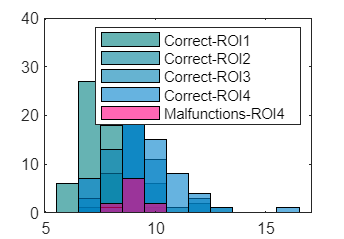

%All Correct ROIS
hCorrect1 =histogram(Correct1,FaceColor = [0 0.5 0.5]);
hold on
hCorrect2 =histogram(Correct2,FaceColor = [0 0.5 0.6]);
hCorrect3 =histogram(Correct3,FaceColor = [0 0.5 0.7]);
hCorrect4 =histogram(Correct4,FaceColor = [0 0.5 0.8]);

%Control/Empty
% hControl =histogram(ControlAll,FaceColor = [1 0.5 0.0]);

%Malfunction
% hMal1 =histogram(Mal1,FaceColor = [1 0 0.5]);
% hMal2 =histogram(Mal2,FaceColor = [1 0 0.5]);
% hMal3 =histogram(Mal3,FaceColor = [1 0 0.5]);
hMal4 =histogram(Mal4,FaceColor = [1 0 0.5]);
% 
% Light Changes
% hLight =histogram(SAll,FaceColor = [0 0.9 0]);

legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Malfunctions-ROI4')

%legend('Correct-ROI1','Correct-ROI2','Correct-ROI3','Correct-ROI4', 'Empty/Control', 'Malfunctions-ROI1','Malfunctions-ROI2','Malfunctions-ROI3','Malfunctions-ROI4','Light Changes')